# **demo15 of Im2mesh package**

demo15 - How to edit polygonal boundaries before meshing

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function poly2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Get boundries from image

We have demostrate how to do this in example3 of demo01.mlx

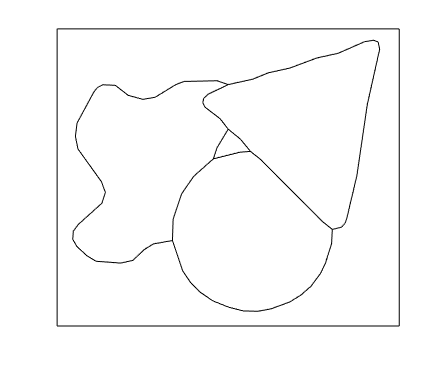

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end

opt = [];   % reset opt
opt.threshold_num_turning = 0;
opt.threshold_num_vert_Smo = 0;
opt.tolerance = 0.3;
opt.threshold_num_vert_Sim = 0;
opt.tf_mesh = false;

[ ~,~,~,~,~,~, bounds ] = im2mesh( im, opt );

% bounds is the simplified polygonal boundaries
plotBounds( bounds );

## Polyshape

It's tedious to edit boundaries directly. Using polyshape object will make things easier. We have demostrated polyshape in demo14. Please take a look at demo14 before you move to demo15.

Here, we use function bound2polyshape to convert a cell array of polygonal boundaries 'bounds' to a cell array of polyshape 'psCell'.

psCell = bound2polyshape(bounds);

Plot cell array of polyshape.

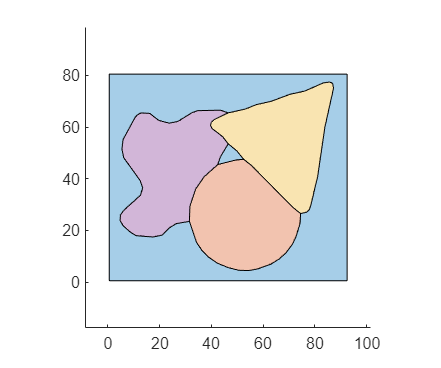

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Coordinates of 4 corners

Before we edit polyshape, we want to know about the x y coordinates of 4 corners in in variable psCell.

The image size is

size(im)

ans =     80    92


The height and width of the input image is 80 and 92, respectively. 

The x y coordinates of 4 corners in variable psCell will be

corners = [0.5, 0.5] + [ 0, 0; 
                         size(im,2), 0; 
                         size(im,2), size(im,1);
                         0, size(im,1) ];
corners

corners =     0.5000    0.5000
   92.5000    0.5000
   92.5000   80.5000
    0.5000   80.5000


The lower left corner is [0.5, 0.5]. The upper right corner is [92.5, 80.5].

I forgot why there is 0.5 shifting in x y coordinates since some code in Im2mesh were written by me many years ago. Perhaps I want to be consistent with MATLAB built-in function bwboundaries.

Let's plot them.

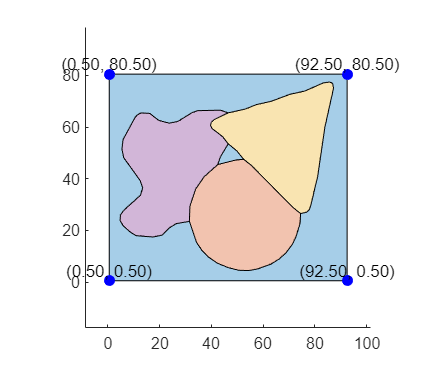

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end

plot(corners(:, 1), corners(:, 2), 'bo', 'MarkerFaceColor', 'b');

% Annotate each point with its coordinates
for i = 1:size(corners, 1)
    text(corners(i, 1), corners(i, 2), ...
        sprintf('(%.2f, %.2f)', corners(i, 1), corners(i, 2)), ...
        'VerticalAlignment', 'bottom', ...
        'HorizontalAlignment', 'center');
end
hold off

Therefore, based on 4 corners, we can know that the mid point of the upper boundary, and the mid point of the right boundary. We will use them later.

% mid point of the upper boundary
xMidUp = 46.5;
yMidUp = 80.5;

% mid point of the right boundary
xMidRight = 92.5;
yMidRight = 40.5;

## Add a block

Let's add a block to the left side of psCell.

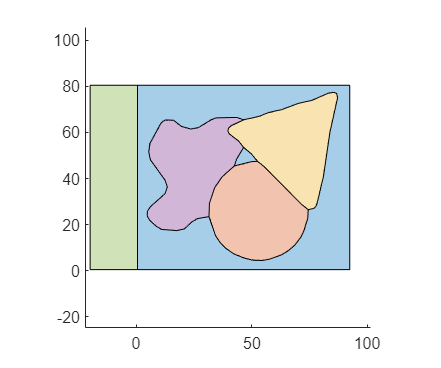

% define a block
vertex = [ -20, 0.5; 0.5, 0.5; 0.5, 80.5; -20, 80.5 ];
psBlock = polyshape(vertex);

% add to the end of psCell
psCell{end+1} = psBlock;

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Merge geometry

We have assumed the block is a new phase in the geometry.

What if the block and the background are in the same phase? We can merge the block into the background.

% psCell{1} is the background. psCell{5} is the block.
% merge the block into the background
psCell{1} = union( psCell{1}, psCell{5} );
psCell{5} = [];     % delete the block

length( psCell )

ans = 5

The length of psCell is 5 although the 5-th element is []. 

To avoid error in the following steps, we need to manually delete empty elements in the cell array.

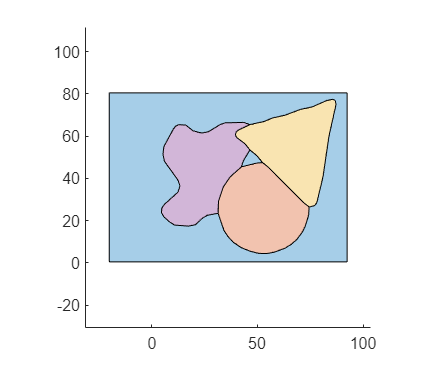

% delete empty elements in cell array
psCell = psCell( ~cellfun('isempty', psCell) );

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add a notch

Let's add a oval-shape notch to the point [xMidUp, yMidUp].

Define a oval. The center of the oval is [xMidUp, yMidUp].

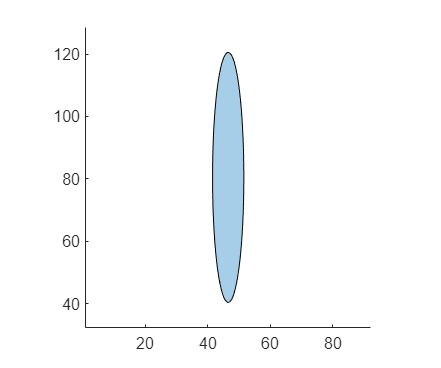

t = 0.05:0.03:2*pi;
x1 = xMidUp + 5*cos(t);
y1 = yMidUp + 40*sin(t);
psNotch = polyshape(x1,y1);
plot( psNotch ); axis equal

Add a oval-shape notch (by boolean operation - subtract).

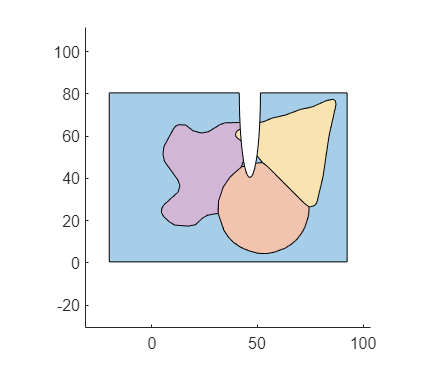

for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psNotch );
end

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add a rod

Let's add a rod to the mid point of the right boundary. The mid point is [xMidRight, yMidRight].

Define a rod. The center of the rod is [xMidRight, yMidRight]. 

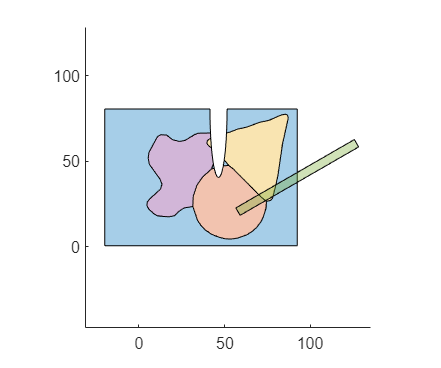

% define a rod
vertex = [ 0 0; 1 0; 1 1; 0 1 ];
psUnitSq = polyshape(vertex);   % unit square
% set length and width
psRod = scale( psUnitSq, [80, 5]);

% set the centroid to [xMidRight, yMidRight]
[xc,yc] = centroid(psRod);
vec = [ xMidRight - xc, yMidRight - yc];
psRod = translate( psRod, vec );

% rotate 30 degree with respect to centroid
[xc,yc] = centroid(psRod);
psRod = rotate( psRod, 30, [xc,yc] );

% plot together
figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
plot( psRod );
hold off

We saw that they are overlapped.

## Boolean operation

We use boolean operations to remove overlapped regions.

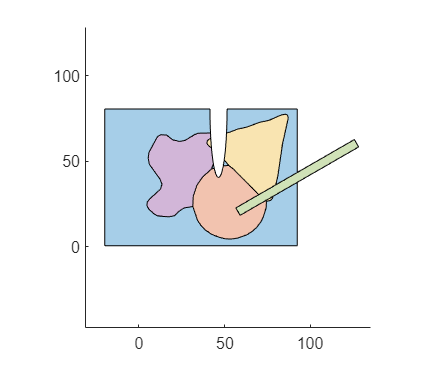

for i = 1: length(psCell)
    psCell{i} = subtract( psCell{i}, psRod );
end

% add to the end of psCell
psCell{end+1} = psRod;

figure
hold on; axis equal;
for i = 1: length(psCell)
    plot(psCell{i});
end
hold off

## Add intersect points

Polyshape objects are not able to find intersect points automatically. Therefore, we convert the cell array of polyshape to a cell array of polygonal boundaries, and use function addIntersectPnts to add intersect points to boundaries. 

Note that if we don't add intersect points, mesh generation will fail.

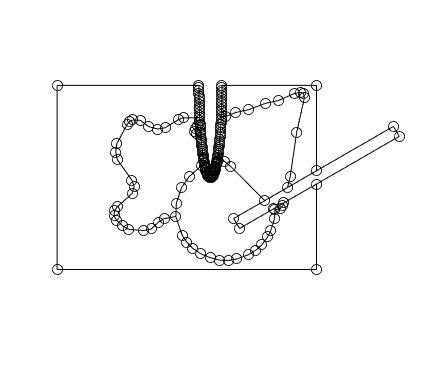

boundsNew = polyshape2bound(psCell);
tol_intersect = 1e-6;   % distance tolerance for intersect
boundsNew = addIntersectPnts( boundsNew, tol_intersect );

% show all vertices
plotBounds( boundsNew, false, 'ko-' );  

Zoom in

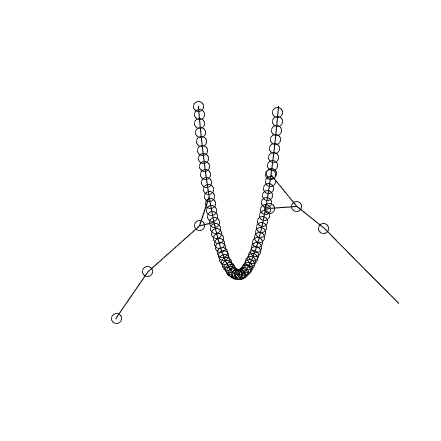

plotBounds( boundsNew, false, 'ko-' )
xlim([27.9 63.0])
ylim([35.9 57.8])

We saw that there are a lot of vertices on the notch.

## Simplify boundaries

We want to reduce the number of vertices on the notch.

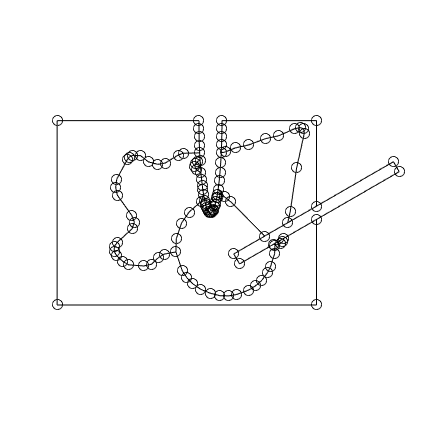

boundsNewCtrlP = getCtrlPnts( boundsNew, false );

tolerance = 0.02;  % for Douglas-Peucker polyline simplification
boundsNewSimplified = simplifyBounds( boundsNewCtrlP, tolerance, 0 );

% show all vertices
plotBounds( boundsNewSimplified, false, 'ko-' );    

Zoom in

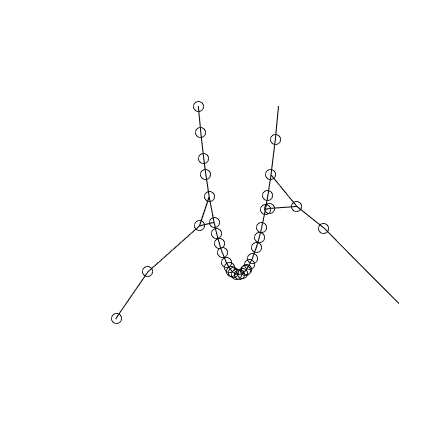

plotBounds( boundsNewSimplified, false, 'ko-' );
xlim([27.9 63.0])
ylim([35.9 57.8])

Wonderful! We saw that the number of vertices on the notch reduced a lot.

Note that you need to adjust the value of tolerance to achieve your desired reduction.

## Generate mesh

To generate mesh, we use function poly2mesh.

Note that function poly2mesh uses [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda) as mesh generator.

[ poly_node, poly_edge ] = getPolyNodeEdge( boundsNewSimplified );

hmax = 500; 
mesh_kind = 'delaunay';
grad_limit = 0.25;
[ vert,tria,tnum,vert2,tria2 ] = poly2mesh( poly_node, poly_edge, hmax, mesh_kind, grad_limit );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                158                188
         10                191                433
         15                194                519


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          9                299                188
         10                299                442
         20                308               1870
         22                308               1886


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                529               1860
     

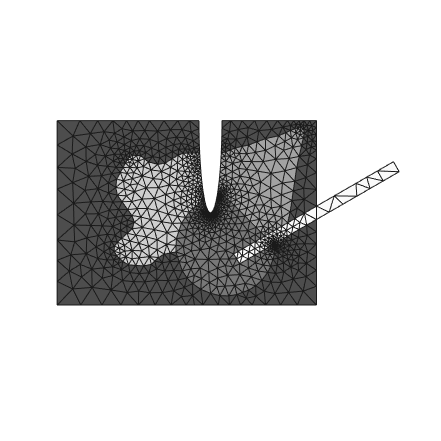

plotMeshes(vert,tria,tnum);

Zoom in

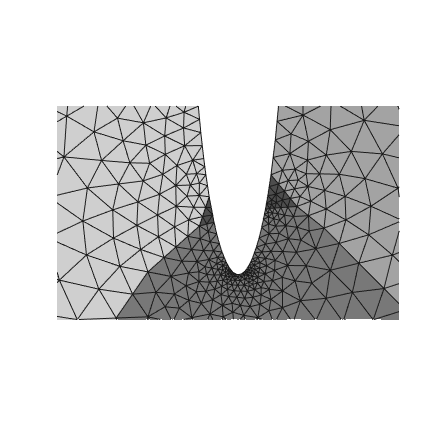

plotMeshes(vert,tria,tnum);
xlim([27.9 63.0])
ylim([35.9 57.8])

Wonderful!

We can also use MATLAB built-in function generateMesh or open-source software Gmsh to generate mesh. We have demonstrated how to do that in other examples of Im2mesh package.

We saw that the mesh in the rod is very coarse. It's possible to refine mesh near a specific polygon boundary. Please refer to demo04 and demo16.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo